%Loading an audio file and fetching the signal and its sampling frequency
[audio_sig, f_s_audio] = audioread('Kanmani Anbodu - Whistle _ Instrumental.mp3');
sound(audio_sig, f_s_audio)

%plotting the spectrogram of the stereo audio as 2 separate channels using
%inbuilt function spectrogram
window_size = 256

window_size = 256

offset = 128

offset = 128

Nfft = window_size

Nfft = 256

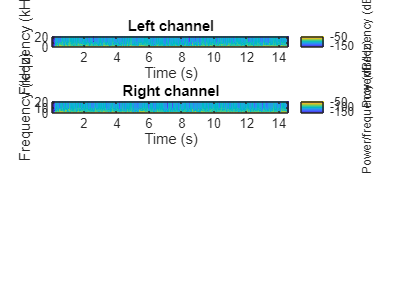


subplot(4,1,1)
spectrogram(audio_sig(:,1), window_size, offset, Nfft, f_s_audio, 'yaxis')
title('Left channel')
subplot(4,1,2)
spectrogram(audio_sig(:,2), window_size, offset, Nfft, f_s_audio, 'yaxis')
title('Right channel')

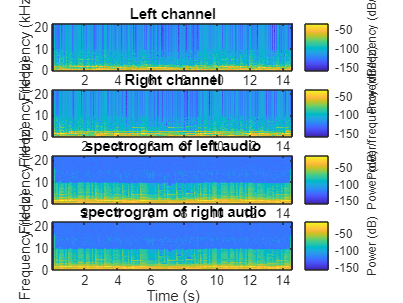

%plotting the audio signal with pspectrum
subplot(4,1,3)
pspectrum(audio_sig(:,1), f_s_audio, 'spectrogram','TimeResolution', 0.05, 'OverlapPercent', 50);
title('spectrogram of left audio')
subplot(4,1,4)
pspectrum(audio_sig(:,2), f_s_audio, 'spectrogram','TimeResolution', 0.05, 'OverlapPercent', 50);
title('spectrogram of right audio')